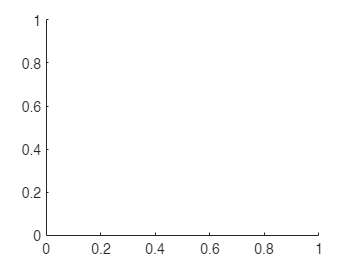

% syms s t;
s = tf('s');
hold off 


student_num = [3 8 1 1 3 5 4 4];
% student_num = [9 3 4 5 3 5 5 3];

sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

zeros_natural = (s+(2*sn_B));
poles_natural = (s+(4*sn_E))*(s+(3*sn_C))*(s+sn_A)*(s+(3i*sn_D)+3*sn_C)*(s-(3i*sn_D)+3*sn_C);
sys_natural = zeros_natural/poles_natural

sys_natural =
 
                              s + 36
  --------------------------------------------------------------
  s^5 + 164 s^4 + 11467 s^3 + 421938 s^2 + 7.616e06 s + 4.859e07
 
Continuous-time transfer function.



adjusted_k = dcgain(sys_natural);

zeros = (s+(2*sn_B));
complex_poles = (s+(3i*sn_D)+3*sn_C)*(s-(3i*sn_D)+3*sn_C)

complex_poles =
 
  s^2 + 66 s + 2178
 
Continuous-time transfer function.



poles = adjusted_k*sn_F*(s+(4*sn_E))*(s+(3*sn_C))*(s+sn_A)*complex_poles;

oltf = minreal(zeros/poles)

oltf =
 
                         8.998e04 s + 3.239e06
  -------------------------------------------------------------------
  s^5 + 164 s^4 + 1.147e04 s^3 + 4.219e05 s^2 + 7.616e06 s + 4.859e07
 
Continuous-time transfer function.




CF = 3*sn_C/2;

H = 2*CF/(s+2*CF);

G = oltf/H; 

% these should be equal!
k = dcgain(oltf)

k = 0.0667

ref = 1/sn_F % value it should be

ref = 0.0667


% TF = KG/(1+KGH)
% KGH = KG/TF-1

[num_ol, den_ol] = tfdata(oltf,'v');

%%%%%%%%%%%
% open loop
C1_GH = oltf;
%%%%%%%%%%

% add the lead controller dynamics to this (Add a pole at 2CF, use a zero
% to cancel out right most pole)

p = 2*CF;
% z = sn_A;
z = sn_E;
% calc 1 ass 7
%%%%%%%%%%%%%%%%%%%%%
C1_D = 1+(p-z)/(z*p)*(s*p)/(s+p)

C1_D =
 
  2.538 s + 33
  ------------
     s + 33
 
Continuous-time transfer function.




C1_Kd = p-z/(p*z)

C1_Kd = 32.9697

%%%%%%%%%%%%%%%%%%%%%%%

Ku = margin(G*H*C1_D)

Ku = 45.5626


K = Ku/2

K = 22.7813


cltf = K*G*C1_D/(1+K*C1_D*G*H)

cltf =
 
                                                                                                                     
   1.717e08 s^10 + 5.357e10 s^9 + 7.611e12 s^8 + 6.473e14 s^7 + 3.633e16 s^6 + 1.397e18 s^5 + 3.697e19 s^4           
                                                                                                                     
                                                                  + 6.6e20 s^3 + 7.543e21 s^2 + 4.944e22 s + 1.403e23
                                                                                                                     
  ---------------------------------------------------------------------------------------------------------------------
                                                                                                                       
  1089 s^13 + 4.65e05 s^12 + 9.318e07 s^11 + 1.159e10 s^10 + 1.003e12 s^9 + 6.402e13 s^8 + 3.118e15 s^7 + 1.176e17 s^6 
                                         

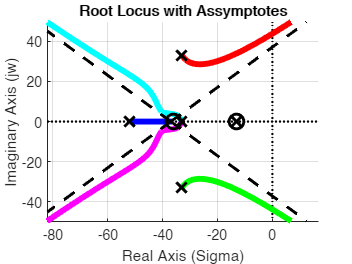

ans = 	1.0e+03 *

  -0.0330 + 0.0330i  -0.0328 + 0.0325i  -0.0327 + 0.0324i  -0.0326 + 0.0323i  -0.0326 + 0.0321i  -0.0324 + 0.0319i  -0.0323 + 0.0317i  -0.0321 + 0.0314i  -0.0319 + 0.0311i  -0.0319 + 0.0311i  -0.0319 + 0.0311i  -0.0318 + 0.0310i  -0.0318 + 0.0310i  -0.0318 + 0.0310i  -0.0318 + 0.0309i  -0.0317 + 0.0308i  -0.0315 + 0.0306i  -0.0310 + 0.0301i  -0.0302 + 0.0295i  -0.0292 + 0.0290i  -0.0286 + 0.0288i  -0.0279 + 0.0286i  -0.0265 + 0.0285i  -0.0249 + 0.0286i  -0.0233 + 0.0289i  -0.0218 + 0.0294i  -0.0202 + 0.0300i  -0.0186 + 0.0307i  -0.0170 + 0.0315i  -0.0153 + 0.0325i  -0.0137 + 0.0335i  -0.0119 + 0.0346i  -0.0102 + 0.0358i  -0.0084 + 0.0371i  -0.0065 + 0.0385i  -0.0046 + 0.0400i  -0.0026 + 0.0415i  -0.0011 + 0.0427i  -0.0010 + 0.0428i  -0.0009 + 0.0429i  -0.0008 + 0.0430i  -0.0007 + 0.0431i  -0.0006 + 0.0432i  -0.0005 + 0.0432i  -0.0004 + 0.0433i  -0.0003 + 0.0434i  -0.0002 + 0.0435i  -0.0001 + 0.0436i  -0.0000 + 0.0437i   0.0001 + 0.0438i
  -0.0330 - 0.0330i  -0.0328 - 


% fig 1
% rla(oltf)
rla(oltf*C1_D)


% Calc 2
%%%%%%%%%%%%%%
C2_T = cltf

C2_T =
 
                                                                                                                     
   1.717e08 s^10 + 5.357e10 s^9 + 7.611e12 s^8 + 6.473e14 s^7 + 3.633e16 s^6 + 1.397e18 s^5 + 3.697e19 s^4           
                                                                                                                     
                                                                  + 6.6e20 s^3 + 7.543e21 s^2 + 4.944e22 s + 1.403e23
                                                                                                                     
  ---------------------------------------------------------------------------------------------------------------------
                                                                                                                       
  1089 s^13 + 4.65e05 s^12 + 9.318e07 s^11 + 1.159e10 s^10 + 1.003e12 s^9 + 6.402e13 s^8 + 3.118e15 s^7 + 1.176e17 s^6 
                                         

C2_Ess = (1 - dcgain(C2_T))*100

C2_Ess = 39.7022

%%%%%%%%%%%%%%


p1 = 2*CF;
% z = sn_A;
z1 = sn_E;
% calc 1 ass 7
%%%%%%%%%%%%%%%%%%%%%
d1 = 1+(p1-z1)/(z1*p1)*(s*p1)/(s+p1)

d1 =
 
  2.538 s + 33
  ------------
     s + 33
 
Continuous-time transfer function.




p2 = 2*CF;
% z = sn_A;
z2 = sn_A+50;
% calc 1 ass 7
%%%%%%%%%%%%%%%%%%%%%
d2 = 1+(p2-z2)/(z2*p2)*(s*p2)/(s+p2);

hold off

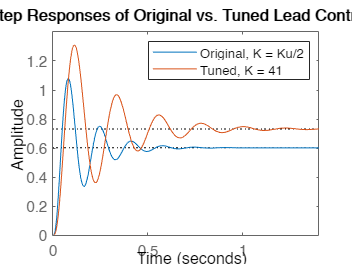

K1 = Ku/2;
cltf_1 = K1*G*d1/(1+K1*d1*G*H);

K2 = Ku*0.9;
cltf_2 = K2*G*d2/(1+K2*d2*G*H);

step(cltf_1);
hold on
step(cltf_2);
title("Step Responses of Original vs. Tuned Lead Controllers")
legend("Original, K = Ku/2", "Tuned, K = 41")
hold off

C4_p = 2*CF;
C4_z = sn_A;
% calc 4 ass 7
%%%%%%%%%%%%%%%%%%%%%
C3_D = 1+(C4_p-C4_z)/(C4_z*C4_p)*(s*C4_p)/(s+C4_p)

C3_D =
 
  2.538 s + 33
  ------------
     s + 33
 
Continuous-time transfer function.



D = C4_D

D =
 
  2.538 s + 33
  ------------
     s + 33
 
Continuous-time transfer function.



dcgain(D)

ans = 1

C3_Kd = (C4_p-C4_z)/(C4_p*C4_z)

C3_Kd = 0.0466


hold off

rla(D*G*H/s)

ans = 	1.0e+03 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0003 + 0.0000i  -0.0004 + 0.0000i  -0.0005 + 0.0000i  -0.0006 + 0.0000i  -0.0008 + 0.0000i  -0.0011 + 0.0000i  -0.0015 + 0.0000i  -0.0020 + 0.0000i  -0.0027 + 0.0000i  -0.0039 + 0.0000i  -0.0061 + 0.0000i  -0.0073 + 0.0000i  -0.0073 + 0.0000i  -0.0073 + 0.0000i  -0.0073 + 0.0000i  -0.0073 + 0.0000i  -0.0073 + 0.0000i  -0.0076 + 0.0000i  -0.0080 + 0.0000i  -0.0095 + 0.0000i  -0.0099 + 0.0000i  -0.0099 + 0.0004i  -0.0094 + 0.0047i  -0.0088 + 0.0067i  -0.0083 + 0.0082i  -0.0070 + 0.0107i  -0.0057 + 0.0129i  -0.0043 + 0.0149i  -0.0028 + 0.0168i  -0.0012 + 0.0185i  -0.0007 + 0.0191i  -0.0006 + 0.0191i  -0.0006 + 0.0192i  -0.0005 + 0.0193i  -0.0004 + 0.0193i  -0.0003 + 0.0194i  -0.0003 + 0.0195i  -0.0002 + 0.0196i  -0.0001 + 0.0196i  -0.0001 + 0.0197i  -0.0000 + 0.0198i
  -0.0330 + 0.0330i  -0.0330 + 

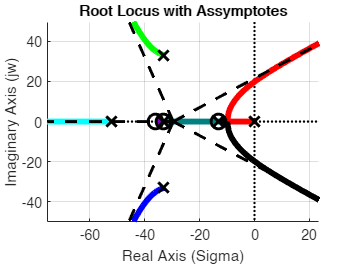

hold off


pid_Ku = margin(C4_D*G*H/s)

pid_Ku = 383.7488

% cltf

C4_T = pid_Ku/2*C4_D*(G/s)/(1+pid_Ku/2*G/s*H*C4_D)

C4_T =
 
                                                                                                                    
  1.446e09 s^11 + 4.512e11 s^10 + 6.41e13 s^9 + 5.451e15 s^8 + 3.059e17 s^7 + 1.176e19 s^6 + 3.114e20 s^5           
                                                                                                                    
                                                           + 5.559e21 s^4 + 6.353e22 s^3 + 4.164e23 s^2 + 1.182e24 s
                                                                                                                    
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  1089 s^15 + 4.65e05 s^14 + 9.318e07 s^13 + 1.159e10 s^12 + 9.971e11 s^11 + 6.248e13 s^10 + 2.932e15 s^9           
                                                       

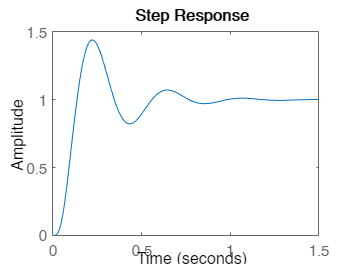

step(C4_T)


C4_ess = (1-dcgain(C4_T))*100

C4_ess = 0

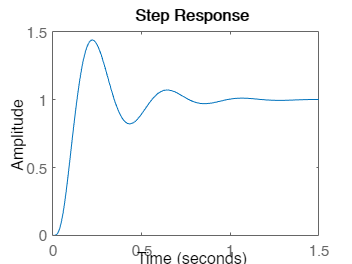


hold off

K = pid_Ku/2

K = 191.8744

pid_cltf = K*G/s*D/(1+K*D*G/s*H)

pid_cltf =
 
                                                                                                                    
  1.446e09 s^11 + 4.512e11 s^10 + 6.41e13 s^9 + 5.451e15 s^8 + 3.059e17 s^7 + 1.176e19 s^6 + 3.114e20 s^5           
                                                                                                                    
                                                           + 5.559e21 s^4 + 6.353e22 s^3 + 4.164e23 s^2 + 1.182e24 s
                                                                                                                    
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  1089 s^15 + 4.65e05 s^14 + 9.318e07 s^13 + 1.159e10 s^12 + 9.971e11 s^11 + 6.248e13 s^10 + 2.932e15 s^9           
                                                   

step(pid_cltf)


maximum = 99999999

maximum = 99999999

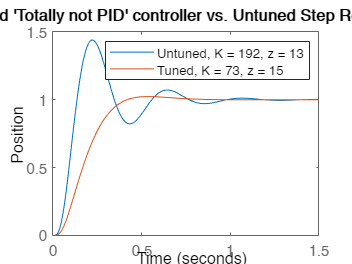

% for z_loop = sn_A:10:100
%     for K_loop = 1:10:pid_Ku
%     
%         D_loop = C4_p/z_loop*(s+z_loop)/(s+C4_p);
%         [y_loop, t_loop] = step(K_loop*G/s*D_loop/(1+K_loop*G/s*D_loop*H));
%         plot(t_loop, y_loop)
%         hold on
%     
%         if max(y_loop) < maximum
%             maximum = max(y_loop);
%             best_z = z_loop;
%             best_K = K_loop;
%         end
%     end
% end
% hold off
best_z = 15;
best_K = pid_Ku*0.19;

step(pid_cltf)
hold on
tuned_D = C4_p/best_z*(s+best_z)/(s+C4_p);
step(best_K*G/s*tuned_D/(1+best_K*G/s*tuned_D*H));
title("Tuned 'Totally not PID' controller vs. Untuned Step Responses")
legend("Untuned, K = 192, z = 13", "Tuned, K = 73, z = 15")
ylabel("Position")

hold off